# Lyapunov function for pendulum

## Parameters

m = 1;
l = 1;
g = 10;
b = 0.2;

x0 = [-3*pi;2*pi];
eigvals = [-0.01 -0.0];
T = 20;
xlims = [-5*pi,5*pi];
ylims = [-3*pi,3*pi];
threshold = Inf;

Declaration of symbolic variables

syms alpha t x1 x2 real
x = [x1;x2];

## State space equation $\dot x = f(x)$

f = [
    x2
    -g/l*sin(x1) - b/m*x2
    ]

$$f = \left(\begin{array}{c} x_{2}\\ -\frac{x_{2}}{5}-10\,\sin\left(x_{1}\right) \end{array}\right)$$

## Lyapunov function $V(x)$

Consider the following Lyapunov function

V = m*g*l*(1-cos(x1)) + 1/2*m*l^2*x2^2;

We generate Matlab typed function handles

V_fh = matlabFunction(V, 'vars', x);
f_ode = matlabFunction(f, 'vars', {t x});
f1_fh = matlabFunction(f(1), 'vars', x);
f2_fh = matlabFunction(f(2), 'vars', x);

Simulate the system $\dot x(t) = f(x(t)), ~ x(0) = x_0$, where $x_0$ is the initial condition

[tt,xx] = ode45(f_ode, linspace(0,T,100*T), x0);

Compute the value of the Lyapunov function along the trajectory: $V(t) := V(x(t))$

V_xx = V_fh(xx(:,1), xx(:,2));

Create a meshgrid in order to plot the Lyapunov function

res = 300;
[x_mesh,y_mesh] = meshgrid(...
    linspace(xlims(1),xlims(2),res),...
    linspace(ylims(1),ylims(2),res));
V_mesh = V_fh(x_mesh,y_mesh);
V_mesh(V_mesh > threshold) = NaN;

Generate the vector field to visualize $f(x)
$

res = 16;
[x_mesh2,y_mesh2] = meshgrid(...
    linspace(xlims(1),xlims(2),res),...
    linspace(ylims(1),ylims(2),res));
v1 = f1_fh(x_mesh2,y_mesh2);
v2 = f2_fh(x_mesh2,y_mesh2);

Normalize the vector field in order that the directions of the trajectories be more visible

r = sqrt(v1.^2 + v2.^2);
v1 = v1 ./ r;
v2 = v2 ./ r;

## Plot

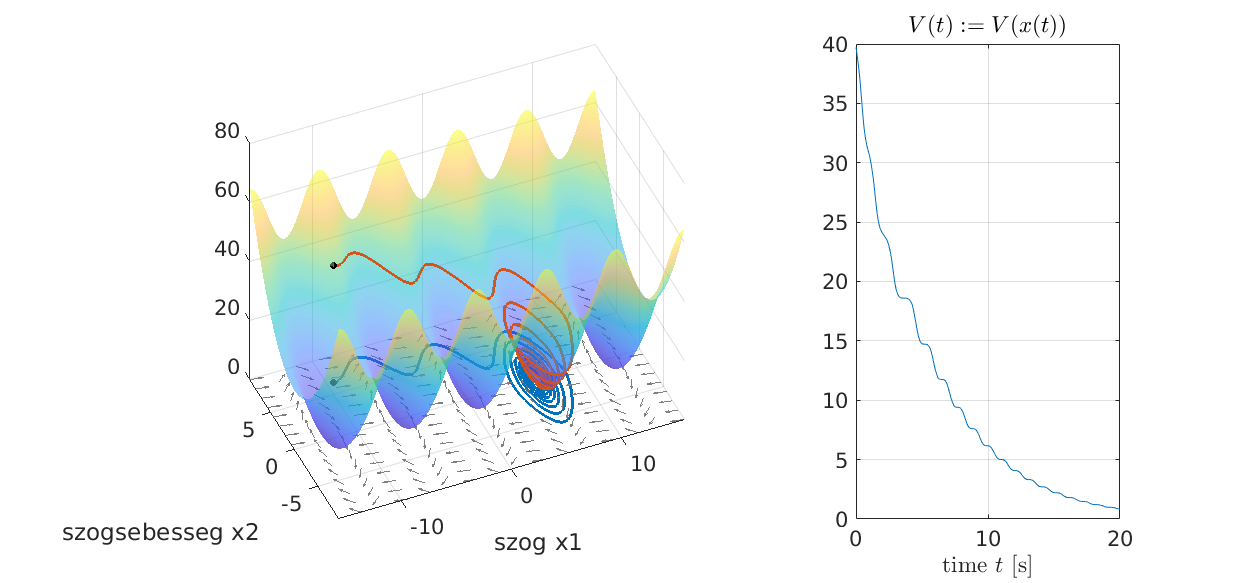

figure('Position', [ 349 368 1238 583 ]), 

subplot(1,3,[1 2])
view([-23.2 42.3]), hold on, grid on
xlim(xlims)
ylim(ylims)
% axis vis3d
plot(xx(:,1), xx(:,2),'linewidth',2)
plot(xx(1,1), xx(1,2),'.k','markersize',15)
plot3(xx(:,1), xx(:,2),V_xx,'linewidth',2)
plot3(xx(1,1), xx(1,2),V_xx(1),'.k','markersize',15)
surf(x_mesh,y_mesh,V_mesh,'facealpha',0.5)
shading interp
ax = gca;
ax.FontSize = 16;
quiver(x_mesh2,y_mesh2,v1,v2,0.5, 'Color', [1 1 1]*0.5);
daspect([2 2 6])
xlabel 'szog x1'
ylabel 'szogsebesseg x2' 

subplot(1,3,3)
plot(tt,V_xx), grid on
title('$V(t) := V(x(t))$', 'interpreter', 'latex','fontsize',22)
xlabel('time $t$ [s]', 'interpreter', 'latex','fontsize',22)
ax = gca;
ax.FontSize = 16;

% set(gcf,'Visible','on')
return

fs = 20;
Ts = 1/fs;

xtlin = interp1(tt,xx,linspace(0,tt(end),T*fs));
V_xtlin = interp1(tt,V_xx,linspace(0,tt(end),T*fs));

phi = xtlin(:,1);

figure
figure('Position', [ 349 368 1238 583 ]), 

S = subplot(1,3,[1 2]);
view([-23.2 42.3]), hold on, grid on
xlim(xlims)
ylim(ylims)
% axis vis3d
plot(xx(1,1), xx(1,2),'.k','markersize',15)
plot3(xx(1,1), xx(1,2),V_xx(1),'.k','markersize',15)
surf(x_mesh,y_mesh,V_mesh,'facealpha',0.5)
shading interp
ax = gca;
ax.FontSize = 16;
quiver(x_mesh2,y_mesh2,v1,v2,0.5, 'Color', [1 1 1]*0.5);
daspect([2 2 6])
xlabel 'szog x1'
ylabel 'szogsebesseg x2' 

clear frames
tic;
for i = 1:numel(phi)
    subplot(S)
    plot(xtlin(i,1), xtlin(i,2),'.b','markersize',7)
    plot3(xtlin(i,1), xtlin(i,2),V_xtlin(i),'.r','markersize',7)

    subplot(133);
    plot([0,sin(phi(i))],[0,-cos(phi(i))],'LineWidth',5);
    axis([-2,2,-2,2])
    daspect([1 1 1])
    drawnow
    dt = toc;
    tic;
    frames(i) = getframe;
    pause(Ts - dt);
end
